clc; 

Features_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Features_v1.csv"; 
Features = readtable(Features_Path); 


Good_Days = Features.GoodDays;
Moderate_Days = Features.ModerateDays;
Unhealthy_for_Sens_Days = Features.UnhealthyForSensitiveGroupsDays;
Unhealthy_Days = Features.UnhealthyDays;
Very_Unhealthy_Days = Features.VeryUnhealthyDays; 
Hazardous_Days = Features.HazardousDays;
Deaths = Features.COVIDDeaths_NormalizedByPopulation_;
Cases = Features.COVIDCases_NormalizedByPopulation_;

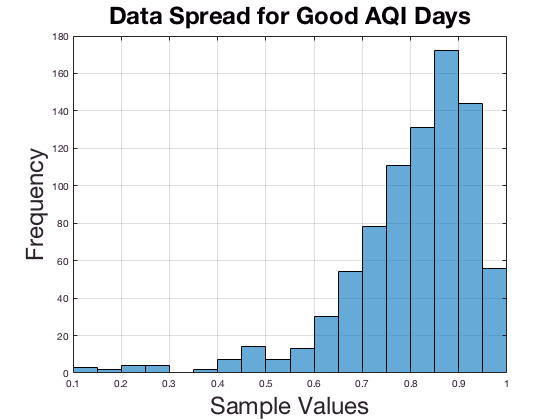

figure(1)
histogram(Good_Days)
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
grid on; 
title('Data Spread for Good AQI Days', 'FontSize', 24)

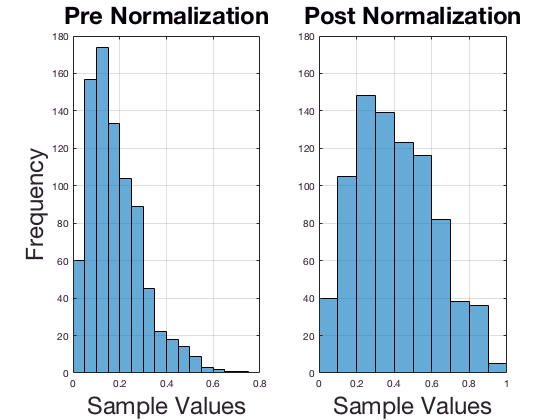

MOD_Sorted = sort(Moderate_Days, 'descend');
A_MOD = atanh(0.95)/MOD_Sorted(1);
normalized_MOD = tanh(A_MOD*Moderate_Days);

figure(2)
subplot(1,2,1)
histogram(Moderate_Days)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ax1 = ylim;
title('Pre Normalization', 'FontSize', 24)

subplot(1,2,2)
histogram(normalized_MOD)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylim(ax1);
title('Post Normalization', 'FontSize', 24)

%suptitle('Data Spread for Moderate AQI Days')

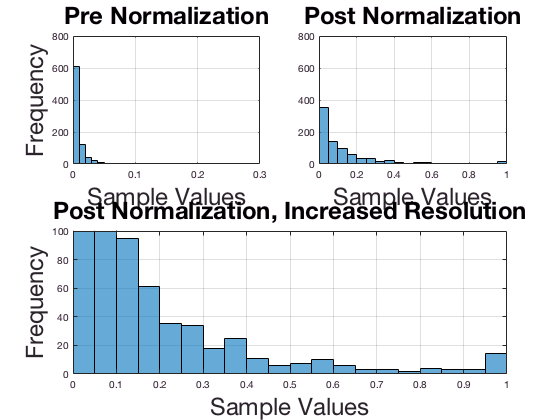

UHS_Sorted = sort(Unhealthy_for_Sens_Days, 'descend');
A_UHS = atanh(0.9999)/UHS_Sorted(1);
normalized_UHS = tanh(A_UHS*Unhealthy_for_Sens_Days);

figure(3)
subplot(2,2,1)
histogram(Unhealthy_for_Sens_Days);
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ax1 = ylim;
title('Pre Normalization', 'FontSize', 24)

subplot(2,2,2)
histogram(normalized_UHS)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylim(ax1);
title('Post Normalization', 'FontSize', 24)

subplot(2,2,[3,4])
histogram(normalized_UHS)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ylim([0 100]);
xlim([0 1]);
title('Post Normalization, Increased Resolution', 'FontSize', 24)


%suptitle('Data Spread for Unhealthy for Sensitive Groups AQI Days')

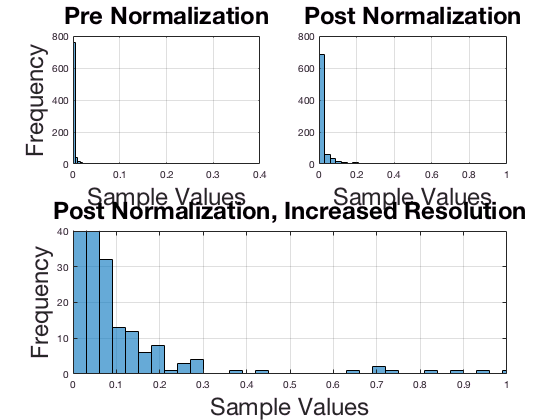

UH_Sorted = sort(Unhealthy_Days, 'descend');
A_UH = atanh(0.9999)/UH_Sorted(1);
normalized_UH = tanh(A_UH*Unhealthy_Days);

figure(4)
subplot(2,2,1)
histogram(Unhealthy_Days)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ax1 = ylim;
title('Pre Normalization', 'FontSize', 24)

subplot(2,2,2)
histogram(normalized_UH)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylim(ax1);
xlim([0:1]);
title('Post Normalization', 'FontSize', 24)

subplot(2,2,[3,4])
histogram(normalized_UH)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ylim([0 40]);
xlim([0 1]);
title('Post Normalization, Increased Resolution', 'FontSize', 24)


%suptitle('Data Spread for Unhealthy AQI Days')

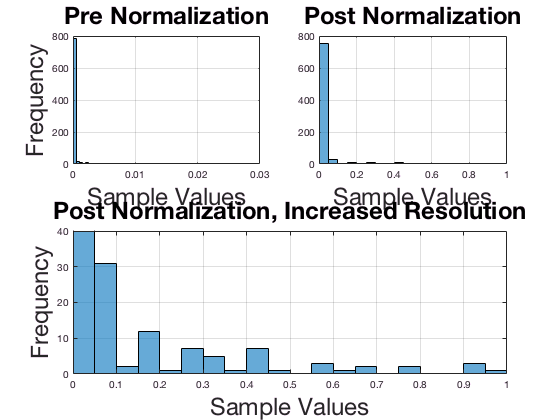

VUH_Sorted = sort(Very_Unhealthy_Days, 'descend');
A_VUH = atanh(0.9999)/VUH_Sorted(1);
normalized_VUH = tanh(A_VUH*Very_Unhealthy_Days);

figure(5)
subplot(2,2,1)
histogram(Very_Unhealthy_Days)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ax1 = ylim;
title('Pre Normalization', 'FontSize', 24)

subplot(2,2,2)
histogram(normalized_VUH)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylim(ax1);
title('Post Normalization', 'FontSize', 24)

subplot(2,2,[3,4])

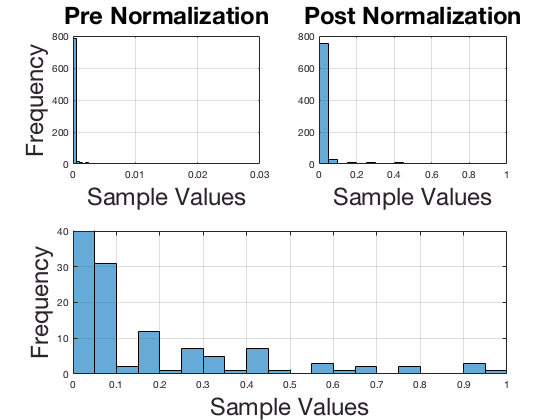

histogram(normalized_VUH)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ylim([0 40]);

%title('Post Normalization, Increased Resolution', 'FontSize', 24)

%suptitle('Data Spread for Very Unhealthy AQI Days')

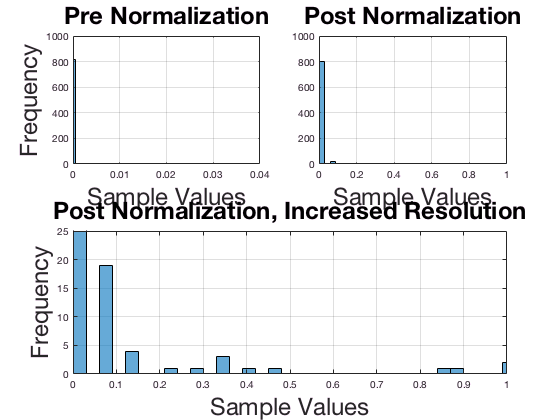

HAZ_Sorted = sort(Hazardous_Days, 'descend');
A_HAZ = atanh(0.9999)/HAZ_Sorted(1);
normalized_HAZ = tanh(A_HAZ*Hazardous_Days);

figure(6)
subplot(2,2,1)
histogram(Hazardous_Days)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ax1 = ylim;
title('Pre Normalization', 'FontSize', 24)

subplot(2,2,2)
histogram(normalized_HAZ)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylim(ax1);
xlim([0:1]);
title('Post Normalization', 'FontSize', 24)

subplot(2,2,[3,4])

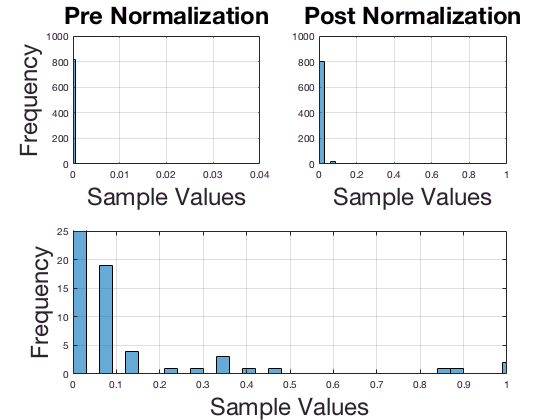

histogram(normalized_HAZ)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ylim([0 25]);
xlim([0 1]);

%title('Post Normalization, Increased Resolution', 'FontSize', 24)

%suptitle('Data Spread for Hazardous AQI Days')

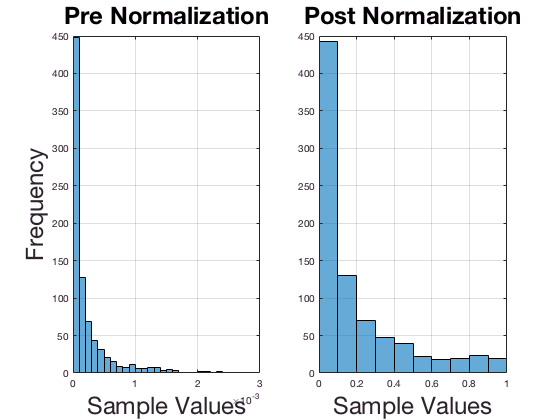

DEATH_Sorted = sort(Deaths, 'descend');
A_DEATH = atanh(0.99)/DEATH_Sorted(1);
normalized_DEATH = tanh(A_DEATH*Deaths);

figure(7)
subplot(1,2,1)
histogram(Deaths)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ax1 = ylim;
title('Pre Normalization', 'FontSize', 24)

subplot(1,2,2)
histogram(normalized_DEATH)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylim(ax1);
title('Post Normalization', 'FontSize', 24)


%suptitle('Data Spread for COVID Deaths')

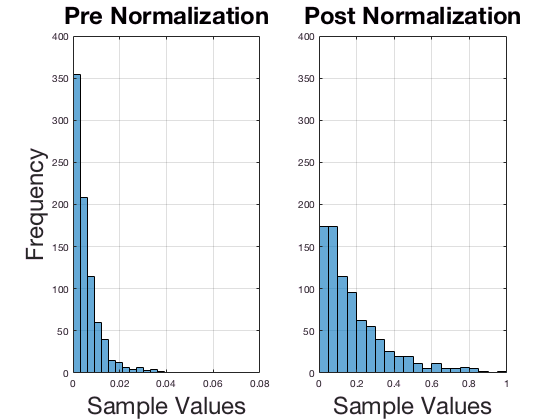

CASES_Sorted = sort(Cases, 'descend');
A_CASES = atanh(0.99)/CASES_Sorted(1);
normalized_CASES = tanh(A_CASES*Cases);

figure(8)
subplot(1,2,1)
histogram(Cases)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylabel('Frequency', 'FontSize', 24)
ax1 = ylim;
title('Pre Normalization', 'FontSize', 24)

subplot(1,2,2)
histogram(normalized_CASES)
grid on;
xlabel('Sample Values', 'FontSize', 24)
ylim(ax1);
title('Post Normalization', 'FontSize', 24)

%suptitle('Data Spread for COVID Cases')


Features_n = Features;

Features_n.ModerateDays = normalized_MOD; 
Features_n.UnhealthyForSensitiveGroupsDays = normalized_UHS;
Features_n.UnhealthyDays=normalized_UH;
Features_n.VeryUnhealthyDays=normalized_VUH; 
Features_n.HazardousDays=normalized_HAZ;
Features_n.COVIDDeaths_NormalizedByPopulation_=normalized_DEATH;
Features_n.COVIDCases_NormalizedByPopulation_=normalized_CASES;

writetable(Features_n, "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Features_v2.csv"); 